# ***Chapter 3 - CAPM and Arbitrage Pricing Theory (APT)***

## *Section A: Capital Asset Pricing Model (CAPM)*

Building on the idea of portfolio diversification and early work of Markowitz's Modern Portfolio Theory, the [CAPM](https://en.wikipedia.org/wiki/Capital_asset_pricing_model) was introduced by William Sharpe in 1964. It marks the birth of asset pricing theory, and it's still widely used nowadays in applications such as evaluating portfolio performance and estimating cost of capital for firms. 

### **Efficient Frontier from Mean-Variance Optimization without Risk-Free Asset in Modern Portfolio Theory**

                                                                                    **maximize**  $\mathit{w^T}\mathit{\mu}$

**                                                                                    subject to ** $\mathit{w^T}\Sigma\mathit{w}\leq\mathit{\sigma^2, \mathit{w^T}e=\text{1}$

where: $\mu$is the expected return vector for all risky assets in the universe and $\Sigma$ is their covariance matrix. $\sigma$ is determined by an investor's risk aversion level.  Given the above settings, one can locate a unique portfolio on efficient frontier for any feasible portfolio risk $\sigma$. 

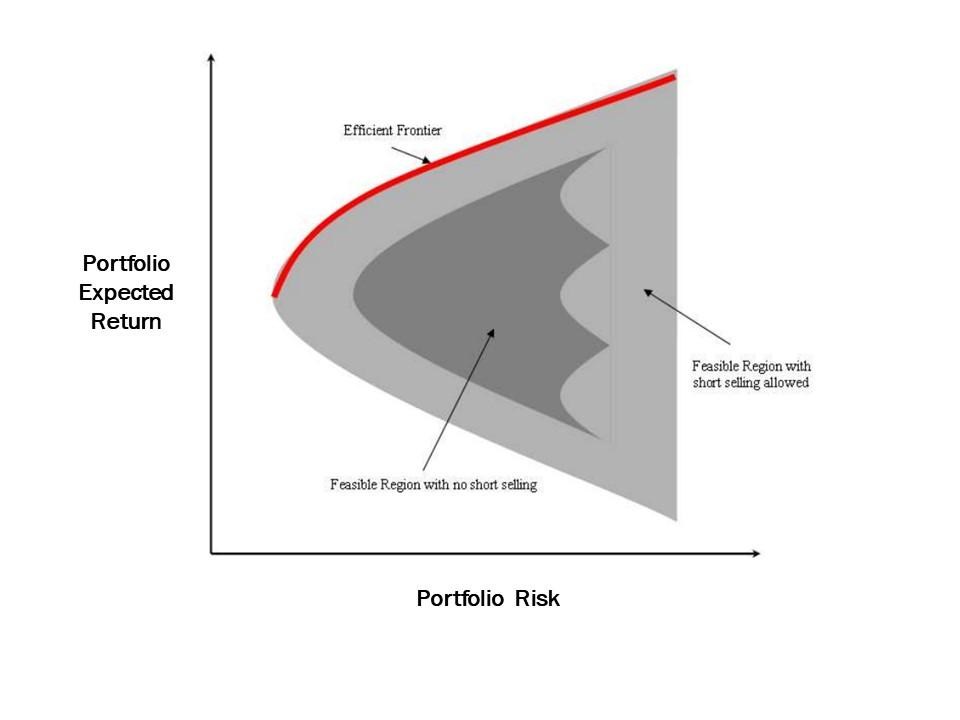

### **How would the efficient frontier change if we introduce the risk-free asset?**

Let's assume the risk-free asset has expected return of $r_f$ (or called *risk-free rate*), and re-run the optimization to solve the optimal weight vector for all risky assets in the universe as follows:

                                                                                    **maximize**  $\mathit{w^T}\mathit{\mu}+(1-w^Te)r_f$

**                                                                                    subject to ** $\mathit{w^T}\Sigma\mathit{w}\leq\mathit{\sigma^2$

Note: 1) the constraint of net leverage of one for all risky assets is scrapped as the portfolio's net leverage of one is maintained by adjusting the risk-free asset weight. 2) the covariance between risk-free asset and any risky asset is always zero. 

The solution for the updated optimzation is: $w^*=\frac{\Sigma^{-1}\mu_{e}}{2\lambda}$, where $\mu_{e}$ is the vector of risky assets' expected excess return over risk-free rate, i.e., for the $i$-th risky asset, $\mu_{e,i}=\mu_i-r_f$, and $\lambda$ is the Lagrange multiplier which is a function of $\sigma$. It's easy to see that the optimal solution must be a combination of risk-free asset and a portfolio on the original mean-variance efficient frontier (why). This portfolio's weight vector can be easily calculated by normalizing the weight vector $w^*$ so that its summation equals one: $w_{opt}=\frac{\Sigma^{-1}\mu_{e}}{e^T\Sigma^{-1}\mu_{e}}$. We've found there exists a unique portfolio on the original efficient frontier so that any new optimal portfolio for the new optimization problem (with risk-free asset) can be represented as a combination of this unique portfolio and the risk-free rate. This portfolio is the Maximum-Sharpe-Ratio portfolio (why), i.e., the tangent portfolio of **Capital Market Line **on the mean-variance efficient frontier. 

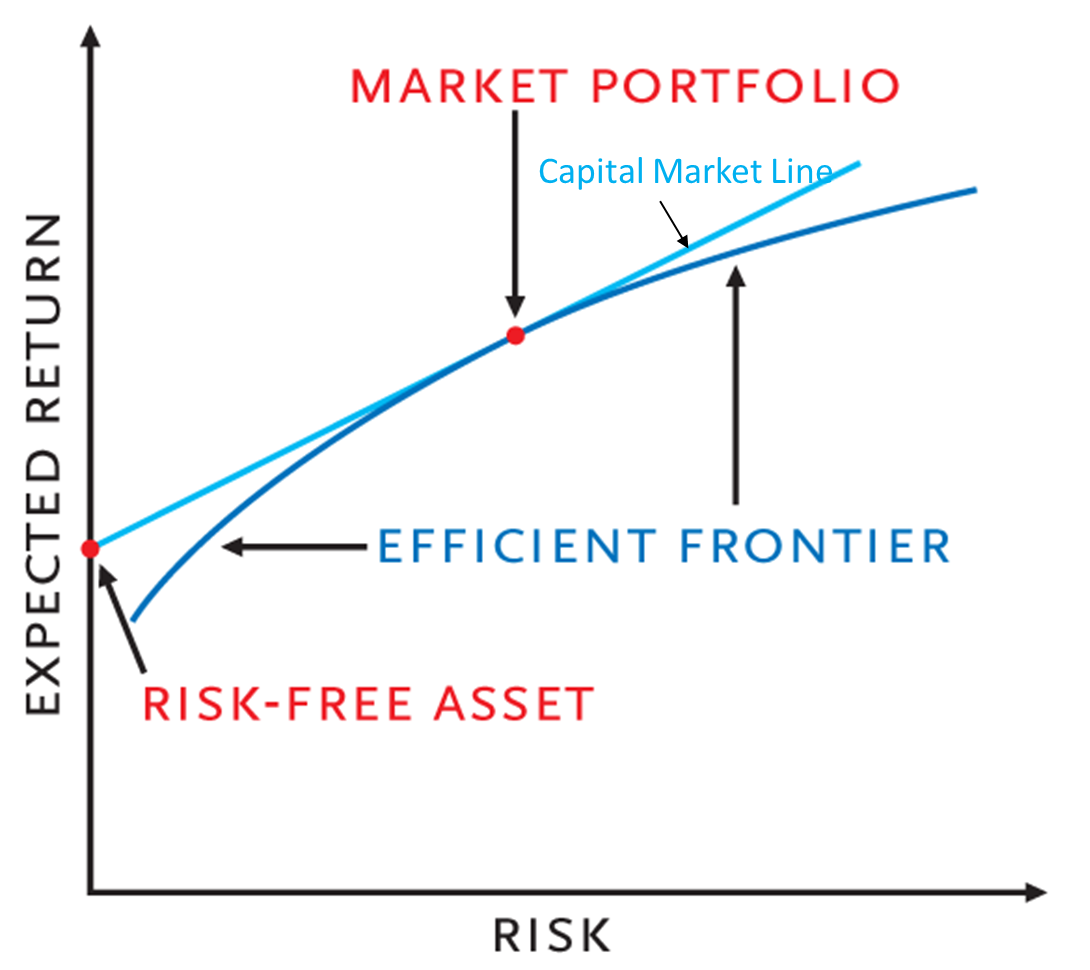

Capital market line (CML) represents all possible cominbations of portfolios consisting in various proportions between risk-free asset and the maximum-Sharpe Ratio portfolio on the mean-variance efficient frontier. Under CAPM assumptions,** a rational investor should only consider portfolios on CML**, therefore, the CML is technically the true efficient frontier considering risk-free asset in the investable universe. For the sake of clarification, we'll reserve the term 'efficient frontier' for the mean-variance efficient frontier of all risky assets, and use CML to denote the one with risk-free asset included. 

***The Maximum-Sharpe-Ratio (MSR) portfolio is the market portfolio because: ****under CAPM assumptions****,*** all investors only invest in the risk-free asset and the MSR portfolio of risky assets, then the weighting of the MSR portfolio must represent the weighting of all risky assets in the market**.** 

*In theory, the market portfolio (or the universe of all risky assets) includes all non-risk-free assets: domestic/foreign stocks, currencies, bonds, commodities, etc. In practice, the market portfolio could be taken as a broad universe of most-traded asset classes in asset allocation models; or the market portfolio can even mean some value-weighted index of domestic equities, such as the S&P 500 index in the U.S. and the Nikkei Index in Japan. *

### **A Risky Asset's Expected Return Is Proportional To The Asset's Exposures to The Market Portfolio**

In equilibrium, when every investor invests in a combination of risk-free asset and the market portfolio, the market portfolio thus becomes visible in the sense that its weighting is observable from the market. For example, say the market is the U.S. equity market, then the market portfolio can be roughly represented by the S&P500 index. On the other hand, the market portfolio has a closed-form formula which is a function of the expected excess returns of risky assets and their covariance matrix. Therefore, the following equation holds:

### $w_{mkt}=\frac{\Sigma^{-1}\mu_{e}}{e^T\Sigma^{-1}\mu_{e}}$,

where the left-hand $w_{market}$ is the observed market portfolio weighting, and the right-hand formula represents the theoretical market portfolio weighting.

***Derivation of the main result in CAPM***

Since $e^T\Sigma^{-1}\mu_{e}$is a scalar value, let's denote it as $c$. 

- Step 1. Multiply $\Sigma$ on both sides: $\Sigma w_{mkt}=\mu_{e}/c$.

- Step 2. Multiply $w_{mkt}^T$on both sides: $w_{mkt}^T\Sigma w_{mkt}=w_{mkt}^T\mu_{e}/c$. Therefore : $c=\frac{w_{mkt}^T\mu_e}{w_{mkt}^T\Sigma w_{mkt}}=\frac{\mu_{e,mkt}}{\sigma_{mkt}^2$, where the numerator is the market portfolio's expected excess return over risk-free rate and the denominator is the market portfolio's variance.

- Step 3. Find the representation of $\mu_e$: replacing $c$ in the Step 1 equation with the result from Step 2, we have $\mu_e=\frac{\Sigma w_{mkt}}{\sigma^2_{mkt}}\cdot\mu_{e,mkt}$.

Note that $\Sigma w_{mkt}$ is a $N\times 1$vector where its $i
$-th element $(\Sigma w_{mkt})_i$ is the covariance between returns of the $i$-th risky asset and the market portfolio. Define$\beta_i=\frac{(\Sigma w_{mkt})_i}{\sigma^2_{mkt}}=\frac{Cov(r_i,r_{mkt})}{Var(r_{mkt})}$, then we have the following CAPM result: $\mu_{e,i}=\beta_i \cdot \mu_{e,mkt}, \forall i,$ i.e., 

### $E(r_i)-r_f=\beta_i\cdot (E(r_{mkt})-r_f)$.

The above pricing equation states that for any asset, its expected excess return is a function of its market beta exposure and the market portfolio's expected excess return. We have observed the following implications of CAPM:

- The return covariance between an asset and the market portfolio determines the asset's beta value

- An asset's market beta measures its exposure to the market (portfolio)

- The expected excess return of an asset is proportional to the expected excess return of the market portfolio

- The expected excess return of an asset is proportional to its market beta

**Why CAPM is a pricing model?**

The security market line (SML) shows the linear relationship between beta (or called systematic risk) and expected excess return. Any asset or fund (portfolio) can find its 'fair pricing' position on SML. The pricing model can be applied to evaluate security performance on ex-post basis (after the fact, or realization, in order to understand what has happened) or on ex-ante basis (to forecast what will happen). 

Wait!! then how can we get the expected excess return of the market portfolio (market risk premium), based on which we use to price security? Assign a long-term market risk premium directly or indirectly. 

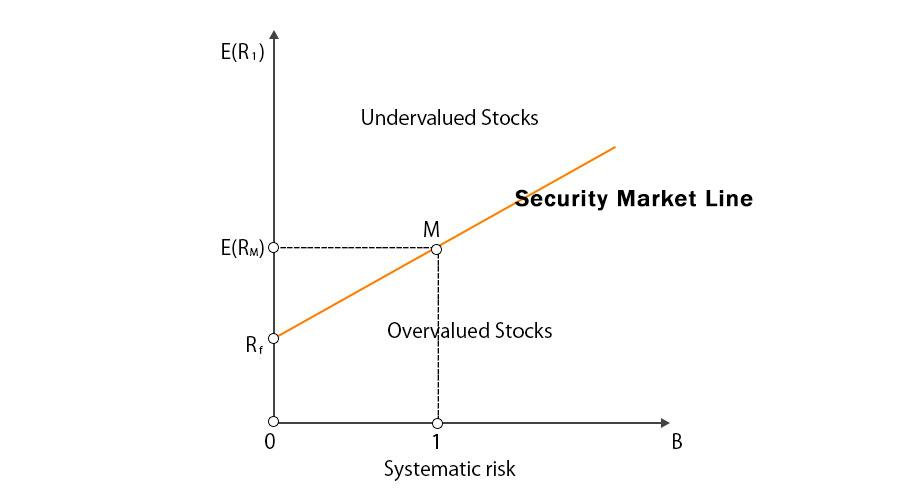

**So does market beta fully characterizes a security's risk exposures? **

No, but it's the only rewarding risk exposures to take according according to CAPM. 

Now let's try to disaggregate a security's return to the return from market exposure and the remaining piece, or the residual return: 

$r_{i,t}-r_f=\beta_i\cdot(r_{mkt,t}-r_f)+\epsilon_{i,t}$.

Then we can break down the security's return variance into systematic (due to the market) and nonsystematic (or idiosyncratic) parts:

$\sigma_i^2=\beta_i^2\sigma_{mkt}^2+var(\epsilon_i)$. 

Note: the above equation holds based on the observation that the market portfolio return is always uncorrelated to the security's residual return, which is unexplainable by market performance. 

CAPM model tells that the expected return for taking any security-level idiosyncratic risk is 0, or in other words, any security's expected residual return equal 0.

Important takeaways:

- Systematic risk, a.k.a, market risk can not be diversified away; while idiosyncratic risk can be reduced through diversification.

- The CAPM forecasts of expected return will only be as good as the forecasts of beta, e.g., the simplest one is to use historical beta).

- Forecasting the market portfolio's expected return is no trivial work, however,we don't need accurate beta return estimate if 1) we don't do market timing but instead always load beta exposure of one (because beta performance doesn't contribute to active return in this case); or if 2) we build a beta-neutral portfolio. 

%%%%  calculate a security's beta to market portfolio
%   load sp500 and three stocks' monthly price data
[blah,blah,rawraw]=xlsread('SecurityMonthlyPrices.xlsx','Sheet1');

Error using xlsread (line 257)
Invoke Error, Dispatch Exception: 
Source: Microsoft Excel
Description: Open method of Workbooks class failed
Help File: xlmain11.chm
Help Context ID: 0


%   security name list
security_name=rawraw(1,2:6);

%   each column is a vector of month-end prices
monthly_price=cell2mat(rawraw(2:26,2:6));

%   transform to monthly returns
monthly_return=monthly_price(2:end,:)./monthly_price(1:end-1,:)*100-100;

%   separate Barcalys AGG, sp500 and the three stocks (AAPL,NFLX, GE)
stock_name=security_name(3:end);
stock_mret=monthly_return(:,3:end);
agg_mret=monthly_return(:,1);
spx_mret=monthly_return(:,2);

%   calculate each security's beta to SP500
beta_vec=nan(3,1);

for i=1:3
    
    %   the covariance matrix between the stock and sp500
    Sigma=cov(stock_mret(:,i),spx_mret);
    
    %   note: beta=covariance/the market's variance
    beta_vec(i)=Sigma(1,2)/Sigma(2,2);
end


%   show scatter plots for each security's monthly returns v.s. SPX monthly
%   returns
for i=1:3
    figure
    scatter(spx_mret,stock_mret(:,i));
    title([stock_name{i},': Beta=',num2str(beta_vec(i),'%.2f')]);
    axis([-50 50 -50 50]);
    pbaspect([1 1 1]);
end

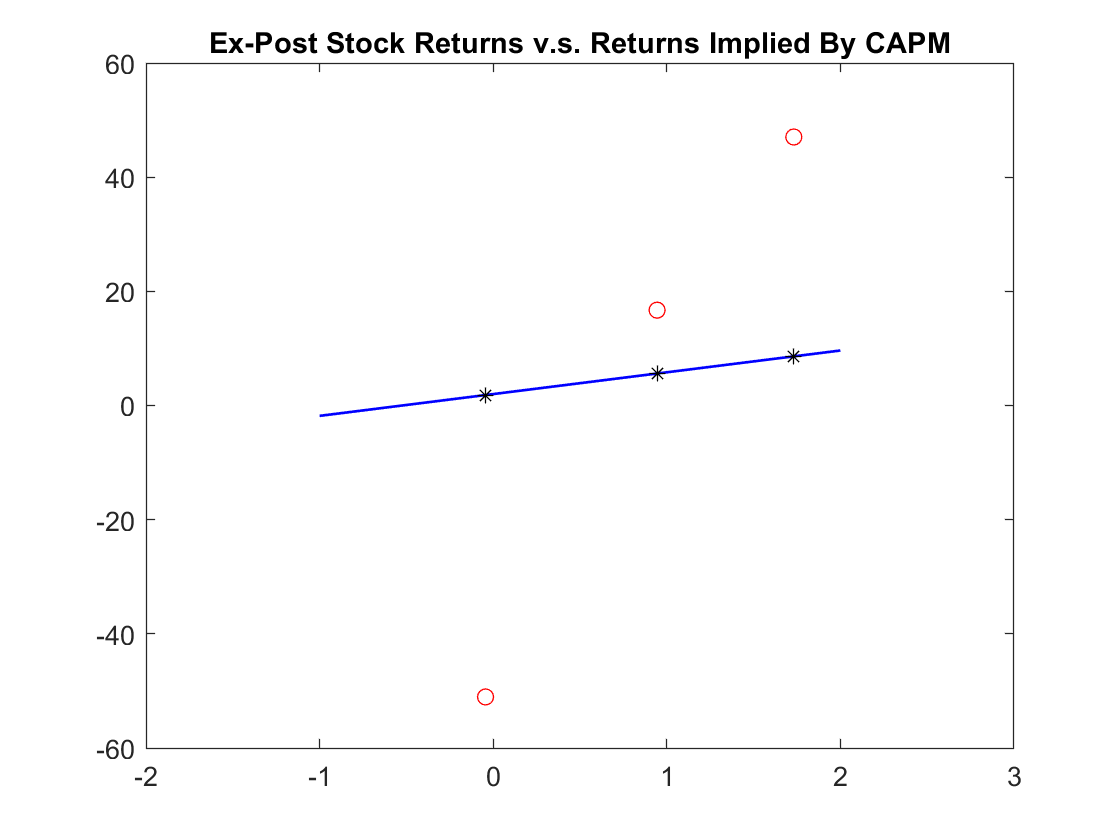

%%%%   evaluate security performance (ex-post) by putting securities' realized performance along with security market line 

%   assume a risk free rate of 2 percent a year
risk_free=2;

%   calculate the market portfolio's realized annualized return in the two years period of [2017,2018]
spx_annret=prod(1+0.01*spx_mret)^0.5*100-100;

%   calculate the three stocks' realized returns in the two years period of [2017,2018]
stock_annret=nan(3,1);
for i=1:3
    stock_annret(i)=prod(1+0.01*stock_mret(:,i))^0.5*100-100;
end

%   calculate the expected return based on CAPM pricing 
stock_exp_annret=risk_free+beta_vec*(spx_annret-risk_free);

%   let's plot the expected vs realized stock returns along with the
%   security market line

%   the two ends for the security market line
x=[-1 2];
y=risk_free+x*(spx_annret-risk_free);

plot(x,y,'b','LineWidth',1)
axis([-2,3,-60,60])
title('Ex-Post Stock Returns v.s. Returns Implied By CAPM')
hold on
p(1)=plot(beta_vec,stock_exp_annret,'k*');
p(2)=plot(beta_vec,stock_annret,'ro');

This example shows residual returns could be significant different than 0 for certain stocks. A great deal of theory and statistical sophistication have been thrown at the question of whether the predictions of the CAPM are indeed observed. One way to refute the CAPM is to build a beta-neutral portfolio which has exhibited consistent and significant positive returns (e.g., addtional factors in APT). 

**Relevance for Active Managers**

The separation of return into market and residual components helps active manager's research. There is no need to forecast market beta performance if you control beta exposures. Active managers could focus research on an security's residual return which has a consensus expectation of zero based on CAPM.

**CAPM is controversial because it's very difficult to identify and test the market portfolio and empirical evidence is mixed. **

Are there alternative pricing models doing better job?

## *Section B: Arbitrage Pricing Theory (APT)*

The Arbitrage Pricing Theory (APT) was primarily developed by Stephen Ross in 1976, more than a decade after William Sharpe et al. published the CAPM model in 1960s. The APT is a substitute for the CAPM which also assumes a factor structure to explain expected returns of assets or portfolios. However, while CAPM is a single factor (the market factor) model, APT has a mulit-factor structure which states that an asset's expected return is a linear function of its loadings to different risk factors. There is no consensus on what constitutes a proper set of risk factors in APT, though the market factor is usually selected as one of the factors in most APT implementations.  The main result of APT is:

#### $    E(r_i)-r_f= \beta_1\cdot(E(r_{f1})-r_f) +\cdot\cdot\cdot+\beta_M\cdot(E(r_{fM}-r_f)$,

where 

- $f1,...,fM$ are M common risk factors

-  $\beta_1,...,\beta_M$are the asset's factor loadings (also called exposures, betas, sensitivities) to those M factors respectively

- $E(r_{fm})-r_f$ is the expected excess return for the risk factor m, also called the factor m's **risk premium.**

#### **Implementation of APT has the following three steps:**

- Identify the risk factors

- Estimate an asset's factor loadings

- Estimate factor risk premia

%   an example of calculating factor loadings in a two-factor APT model where:
%   equity market factor is represented by SP500
%   fixed-income market factor is represented by Barclays AGG
for i=1:1
    fprintf('----- Stock Ticker: %s -----\n',stock_name{i});
    
    %   market exposure in CAPM (note: here the market is SP500)
    fprintf('--Under CAPM--\n');
    fitlm(spx_mret,stock_mret(:,i))
    
    %   two factor exposures in APT (one for equity market factor and one
    %   for fixed-income market factor)
    fprintf('--Under Two-Factor APT--\n');
    fitlm([spx_mret,agg_mret],stock_mret(:,i))
end

----- Stock Ticker: AAPL -----


--Under CAPM--


ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat      pValue 
                   ________    _______    _______    ________

    (Intercept)     1.1323      1.6361    0.69205     0.49615
    x1             0.94413     0.49947     1.8902    0.071972


Number of observations: 24, Error degrees of freedom: 22
Root Mean Squared Error: 7.91
R-squared: 0.14,  Adjusted R-Squared 0.101
F-statistic vs. constant model: 3.57, p-value = 0.072

--Under Two-Factor APT--


ans = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate      SE        tStat      pValue 
                   ________    _______    _______    ________

    (Intercept)    0.89444      1.7085    0.52352     0.60609
    x1             0.99558     0.51437     1.9355    0.066503
    x2              1.4241      2.4013    0.59306     0.55948


Number of observations: 24, Error degrees of freedom: 21
Root Mean Squared Error: 8.03
R-squared: 0.154,  Adjusted R-Squared 0.0733
F-statistic vs. constant model: 1.91, p-value = 0.173

In the above example, after we chose the two factors, estimating an asset's factor loadings and factor risk premia is relatively easy, however, as evidenced by the results, this arbitraily specified APT model didn't add value at all. So what went wrong? 

For this specific example and indeed **for most APT implemenations, everything starts with a reasonable and 'correct' model specification, i.e., knowing what the risk factors are. **This is both an advantage and an disadvantage of APT: it's flexible enough that practitioners with domain knowledge can easily customize their choices of risk factors for different assets they are dealing with; on the other side, it introduces ambiguity in the selection and number of factors to be used in a APT model. 

#### How to select risk factors to build a robust APT pricing model?

Short answer: it depends on your experiences and knowledge on the assets you are dealing with. There doesnot exist a unique set of risk factors which is applicable for all different assets. That's the biggest challenge and one main difficulty in APT implementation. 

## Main categories of risk factors 

#### Responses to External Influences

Examples: sector/industry specific events, macroeconomic data such as GDP growth, inflation changes, economic activity measures, and changes in foreign exhange rates, change in oil prices, etc. 

#### Cross-Sectional Comparisons

Examples: fundamental attributes such as valuation, growth, quality, leverage, etc; and market attributes such as momentum, volatility, beta, etc. 

#### Statistical Factors

Examples: principal compoments from PCA, ICA, or pattern-based attributes based on any statistical model. 

**Rule of thumb in factor selection**:  factors should be incisive to provide significant explantory power for asset returns; and factors should be intuitive in terms of interpretable and recognizable, which requires investment intuition. 

*We will spend time in the latter part of this course to explore different factors and build portfolios to capture individual factor risk premium. *